# **Communication scheme with the IRS-assisted link and transmission 802.11ad**

Description: This file caculates the pathloss, SNR, and PER observed by the MU at the ground plane; see Fig. 1. The code implements the connection of the transmitter; which produces 802.11ad frames, with the IRS and the MU. At the MU, this code also implements the complete pipeline for the communication scheme; see Fig. 2. Results are stored in the `simulation_results` file with the following arrays:

- `pathloss` matrix: It is a 50x50 matrix that stores the pathloss values in polar coordinates centered at the illuminated area. The indexes of this matrix refer to the polar coordinates with the center on the illuminated area. Each row in the `PER` matrix denotes the radius in the range 0 (center) to `radius_MU` (see the Parameters file). Each column is the angle in the interval $[0,\,2\pi]$.

- `SNR` matrix: It is a 50x50 matrix that stores the SNR values in polar coordinates centered at the illuminated area. The indexes of this matrix refer to the polar coordinates with the center on the illuminated area. Each row in the `PER` matrix denotes the radius in the range 0 (center) to `radius_MU` (see the Parameters file). Each column is the angle in the interval $[0,\,2\pi]$.

- `PER` matrix: It is a 50x50 matrix that stores the PER values in polar coordinates centered at the illuminated area. The indexes of this matrix refer to the polar coordinates with the center on the illuminated area. Each row in the `PER` matrix denotes the radius in the range 0 (center) to `radius_MU` (see the Parameters file). Each column is the angle in the interval $[0,\,2\pi]$.

- `troughput` array: It is column vector that evaluates the throughput with the radius.

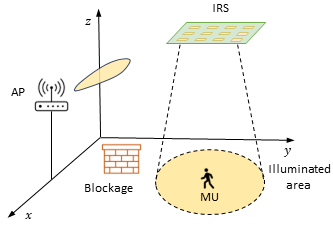

Fig 1: IRS-assisted link between an access point (AP) and a mobile user (MU).

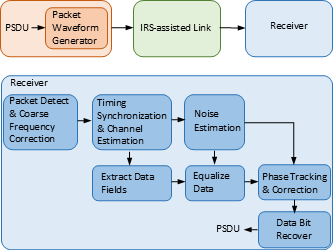

Fig. 2: Block diagram for the implemented transmission-reception scheme with the 802.11ad std.

**Parameters**

Parameters

Unable to resolve the name 'ind.DMGData'.

Error in Parameters (line 110)
idx = (1:ind.DMGData(2));

IRS_config
pos_MU = p_focus;%the MU's position is centered at the IRS focus

#### 802.11ad transmissions

%pre-allocating space for the arrays SNR, pathloss and PER
SNR_rad_ang_dB=zeros(total_pos_points,total_pos_points);
pathloss_rad_ang=zeros(total_pos_points,total_pos_points);
packet_errors_rad_ang=zeros(total_pos_points,total_pos_points);
numPacketErrors = 0;%counter for the total of errors

%Reading the indices of the packet frame, used to later identify the begining and the
%end of data blocks in the wifi packet
ind = wlanFieldIndices(cfgDMG);

numPkt = 1; % Index of the transmitted packet

%indices for the location of the MU coordinates, these indices are used to
%index the right position in the SNR and pathloss matrix pre-comupted
%within the IRS_config.mlx file
pos_MU_idy=0;
pos_MU_idz=0;
%recover the index for the data portion within the packet
idx = (1:ind.DMGData(2));
planeWave=zeros(1,ind.DMGTRN(2));

Li = (lambda/(2*pi*norm(p_IRS-p_AP)));%power loss in the direct link AP-IRS

tic;
for i_radius=1:total_pos_points%loop in the radial dimension
    %printing the progress within the loop
    disp(['r=',num2str(i_radius/total_pos_points*100,3),'%']);
    for i_ang=1:total_pos_points %loop in the angular dimension

        
        %The MU moves in circles paralel to the yz-plane and
        %centered at p_focus.
        %calculating the MU position in the plane parallel to yz and
        %distant from it in the amount (IRS_height-MU_height)
        pos_MU(2)=r_MU(i_radius)*cos(angle_MU(i_ang))+p_focus(2);
        pos_MU(3)=r_MU(i_radius)*sin(angle_MU(i_ang))+p_focus(3);        
        pos_MU_idy=ceil((pos_MU(2)-p_focus(2))/Dobs*N)+floor(N/2);
        pos_MU_idz=ceil((pos_MU(3)-p_focus(3))/Dobs*N)+floor(N/2);

        %validate the indexes to be less than the amount of points in the
        %ground plane given by N
        if pos_MU_idy>N
            pos_MU_idy=N;
        elseif pos_MU_idz>N
            pos_MU_idz=N;
        end

        
        for f=1:numPackets %loop in the total of packets per position
            %802.11n waveform generation
%             % Set random substream index per iteration to ensure that each
%             % iteration uses a repeatable set of random numbers
%             stream = RandStream('combRecursive','Seed',1);
%             stream.Substream = isnr;
%             RandStream.setGlobalStream(stream);
            %PDSU: random generation of Bytes
            % Generate a packet waveform
            psdu = randi([0 1],cfgDMG.PSDULength*8,1);      
            txWaveform = wlanWaveformGenerator(psdu,cfgDMG);
            % Add delay and trailing zeros accounting for channel
            % impairments
            % Get the plane wave while applying the AWV to the preamble, header, and data                    
            %tx = [zeros(delay,1); txWaveform; zeros(zeroPadding,1)];

            %power loss in the direct link IRS-MU
            Lr = (lambda/(2*pi*norm(pos_MU-p_IRS)));
            %performing calculations for the emission (Radiator); AP-IRS
            %link (PLi-term); IRS coeff (g_irs-term); reception (Collector)
            rx_chan = [zeros(delay,1);...
                  Collector(Lr*abs(g_irs(pos_MU_idy,pos_MU_idz))*Li*Radiator(txWaveform(idx),steerAngle,preambleDataAWV),[0;0]);...
                  zeros(zeroPadding,1)];

            
            %IRS gain and channel noise
            %the SNR array includes the impact of path loss, IRS gain and
            %noise, it is missing the transmitter and receiver antennas gain
            %rx = awgn(tx,pow2db(SNR(pos_MU_idy,pos_MU_idz))+pow2db(bandpower(tx)));
            % rx = awgn(tx,25);
            rx=rx_chan+wgn(idx(end)+delay+zeroPadding,1,var_noise_dB,'complex');

            % Add carrier frequency offset (CFO)
            rx = frequencyOffset(rx,fs,freqOffset);

            % Packet detection
            threshold = 0.03; % Good for low SNRs
            pktStartOffset = dmgPacketDetect(rx,0,threshold);
            if isempty(pktStartOffset) % If empty no STF detected; packet error
                numPacketErrors = numPacketErrors+1;
                numPkt = numPkt+1;
                continue; % Go to next loop iteration
            end
            
            % Frequency offset estimation and correction
            stf = rx(pktStartOffset+(ind.DMGSTF(1):ind.DMGSTF(2)));
            fOffsetEst = dmgCFOEstimate(stf);
            rx = frequencyOffset(rx,fs,-fOffsetEst);

            % Symbol timing and channel estimate
            preamblefield = rx(pktStartOffset+1:pktStartOffset+ind.DMGHeader(2),:);
            [symbolTimingOffset,chanEst] = dmgTimingAndChannelEstimate(preamblefield);
            startOffset = pktStartOffset+symbolTimingOffset;
            
            % If not enough samples to decode detected data field start,
            % then assume synchronization error and packet error
            if (startOffset+ind.DMGData(2))>size(rx,1)
                numPacketErrors = numPacketErrors+1;
                numPkt = numPkt+1;
                continue; % Go to next loop iteration
            end

            % Noise estimation using the STF as repeating sequence
            stf = rx(pktStartOffset+(ind.DMGSTF(1):ind.DMGSTF(2)));
            nVarEst = dmgSTFNoiseEstimate(stf);

            % Extract data field (ignore first GI)
            rxData = rx(startOffset+((ind.DMGData(1)+Ngi):ind.DMGData(2)));

            % Linear frequency domain equalization
            rxEqDataBlks = dmgSingleCarrierFDE(rxData,chanEst,nVarEst);

            % Unique word phase tracking
            rxEqDataBlks = dmgUniqueWordPhaseTracking(rxEqDataBlks);

            % Discard GI from all blocks
            rxDataSym = rxEqDataBlks(1:end-Ngi,:); 

            % Recover the transmitted PSDU from DMG Data field
            dataDecode = wlanDMGDataBitRecover(rxDataSym,nVarEst,cfgDMG);

            % Determine if any bits are in error, i.e. a packet error
            packetError = any(biterr(psdu,dataDecode));
            numPacketErrors = numPacketErrors+packetError;
            numPkt = numPkt+1;   
           
        end
        %updating the values for the SNR and PER
        pathloss_rad_ang(i_radius,i_ang)=path_loss(pos_MU_idy,pos_MU_idz);
        SNR_rad_ang_dB(i_radius,i_ang)=pow2db(bandpower(rx_chan))-var_noise_dB;
        packet_errors_rad_ang(i_radius,i_ang)=numPacketErrors;
        numPacketErrors=0;
        numPkt=0;
    end

    %printing the progress withing the loop
    disp(['SNR=',num2str(pow2db(SNR(pos_MU_idy,pos_MU_idz))),...
        ', numPacketErrors->',num2str(sum(packet_errors_rad_ang(i_radius,:)))]);

    save simulation_results_MCS_12 packet_errors_rad_ang SNR_rad_ang_dB pathloss_rad_ang;
end
toc;

%evaluating throughput in Mbps per radius value
%total of packets with errors per radius value
numPacketErrors=sum(packet_errors_rad_ang,2);
fs = wlanSampleRate(cfgDMG);%sampling frequency
txtime = (length(txWaveform)/fs); % Packet duration
throughput=1e-6*((numPackets*total_pos_points-numPacketErrors)*(8*cfgDMG.PSDULength)/((numPackets*total_pos_points)*(txtime*total_pos_points+idleTime*1e-6)));

save simulation_results_MCS_12 packet_errors_rad_ang SNR_rad_ang_dB pathloss_rad_ang throughput;